# ***Εργασία 2024 (REPORT)***

### *Χρήστος Λεβαντής, 321-2020110*

% Γενικά, τα script έχουνε σχόλια, Οπότε δεν γράφω πολλές 
% περιγραφές στην αναφορά γιατί θεωρώ είναι καλύτερο να τα εξηγώ 
% μέσα στον κώδικα για να καταλαβαίνεται που απευθύνομαι κάθε φορά.
% Απλά είναι στα ελληνικά και άμα έχετε
% παλία έκδοση MATLAB μάλλον δεν θα τα διαβάσει (δεν το σκέφτηκα από την άρχη συγνώμη)
% --
% Κάλο είναι να τρέχετε τις συνάρτήσεις μια μια, και όχι όλες μαζί γιατι
% εξαρτώνται η μια από την άλλη και κάποιες φορές το MATLAB τις μπερδέυει και δεν 
% περιμένει να τελιώσει η μια για να ξεκινήσει η άλλη.

## Ερώτημα 1

% Κάλουμε συνάρτηση
messageSource_1();

Η εντροπία της πηγής είναι: 0.38 bits


## Ερώτημα 2

% Κάλουμε συνάρτηση
local_randomness_2();

Η εντροπία της τυχαιότητας είναι: 6.00 bits
Η υπό συνθήκη εντροπία είναι: 3.00 bits
Η αμοιβαία πληροφορία είναι: 3.00 bits


## Ερώτημα 3

% Κάλουμε συνάρτηση
apply_crc_3();
% Ουσιαστικά κάνω CRC στα μηνύματα του ερωτήματος 2 ('new_message_series_2.mat', 'new_messages')
% Το σημαντικό είναι να πούμε ότι όλα τα μηνήματα του ερωτήματος 2
% μετατρέπονται σε 8 bits. Οπότε για παράδειγμα άμα πάρουμε το πρώτο μήνυμα
% το οποιο έιναι το 50 αυτό σε binary μορφή είναι το 110010, σε 8-bits
% είναι το 00110010. Δεν έχει κάμια σημασία άμα κάνουμε CRC στο 110010 και
% το 00110010 το ίδιο αποτέλεσμα θα έχουμε. Οπότε όπως θα δούμε και στα
% αποτελέσματα της συνάρτησης apply_crc_3(); ('new_data_3.mat', 'new_data')
% το τελικό είναι --> 
% 0	 0	1	1	0	0	1	0	0	1	0	0	0	0	1	1	0	1	0	0	1	0	1	0	0	1	1	0	1	1	0	1
% (32-bits, 8 + 24) Το οποίο είναι σωστό τουλάχιστον με το online calculator 
% https://asecuritysite.com/comms/crc_div

## Ερώτημα 4

% Κάλουμε συνάρτηση
apply_hamming_coding_4();
% Βοήθεια για κατανόηση Hamming coding:
% https://www.youtube.com/watch?v=WdmGSWrcMvM
% --
% Στην εκφώνηση ζητά να γίνει κωδικοποιήση σε 24 bits
% έγω στο προηγούμενο ερώτημα έβγαλα τα μηνύματα σε 32 bits.
% Προσπάθησα να χρησιμοποιήσω την comm.HammingEncoder αλλά δεν
% υποστηρίζεται σε νέες εκδόσεις.
% --
% Κάθε 4-bit θα κωδικοποιηθεί σε 7-bit κωδικολέξη.
% Οπότε έχουμε μηνύματα με μέγεθος 32-bit άρα 32/4 = 8bit
% Τελικά θα έχουμε 8 * 7 = 56 bit μέγεθος κάθε μηνύματος.
% Συνολικά bits 56 * 100000 = 5600000 bits
% --
% Οι πιθανές λέξεις: Αφού χρησιμοποιώ Hamming(7, 4) που αντιστοιχίζει 
% μηνύματα 4-bit σε κωδικοποιημένες λέξεις 7-bit. Υπάρχουν λοιπόν 2^4 = 16
% πιθανές λέξεις καθέ μια να αντιστοιχίζεται σε 7-bit κωδικολέξη. 
% Καταλαβαίνουμε ότι 2^7 = 128 πιθανές κωδικολέξεις.
% Επίσης δωσμένου ότι αρχικά έχουμε 32-bit μηνύματα 32/4 = 8 segments
% ο συνολικός αριθμός των 56 λέξεων είναι 2^4*8 = 2^32.
% --
% Γενικά για να υλοποιήσω την συνάρτηση ακολούθησαν ακριβώς ότι λέει η
% διαφάνεια στο eclass.
% Έχω κάνει έλεγχο για το πρώτο μήνυμα για κάθε 4bit κομμάτι του με βάση
% την ιστοσελίδα https://www.compscilib.com/calculate/hamming-code?variation=default
% και δουλέυει σωστά.
% στην συνάρτηση test_hamming() είναι η συνάρτηση που χρησιμοποιώ και στην 
% apply_hamming_coding_4();

#### Για υπολογισμό των πιθανοτήτων εμφάνισης έχουμε την συνάρτηση (Ερώτημα 4)

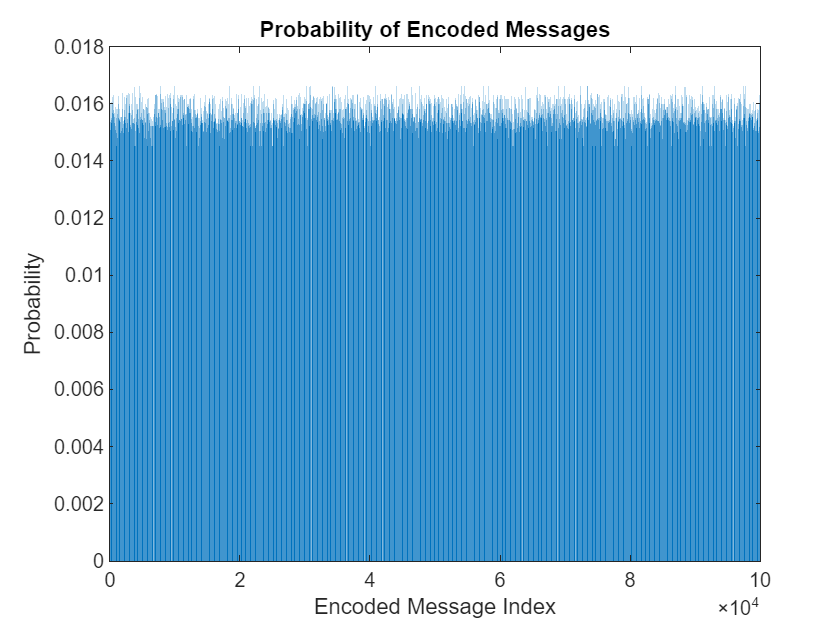

calculate_probabilities_4();

% Μετά την εκτέλεση αυτής θα δούμε ότι όλες οι πιθανότητες είναι κοντά
% στο 0,016 κάτι το οποίο δείχνει ομοιόμορφη κατανομή.

## Ερώτημα 5ο

     0     1     0     0     1     1
     0     0     0     1     0     0
     1     0     0     0     0     0
     1     1     1     1     1     1
     1     0     1     0     1     1
     1     1     1     1     0     0
     0     0     1     0     0     0
     0     1     0     1     1     0
     0     0     0     0     1     0
     1     1     1     0     1     0

     0     0     1     1     1     0
     0     0     1     1     1     0
     1     0     0     1     1     1
     1     1     1     1     0     0
     1     1     0     1     1     1
     1     1     1     1     0     1
     0     1     0     0     1     0
     1     1     1     0     0     0
     1     1     1     1     1     0
     0     1     1     0     1     0

     0     0     0     0     1     1
     0     1     1     0     1     1
     0     0     1     1     1     1
     0     1     0     1     1     1
     0     1     0     1     0     1
     0     0     1     1     0     1
     0     1     1     0     0     0

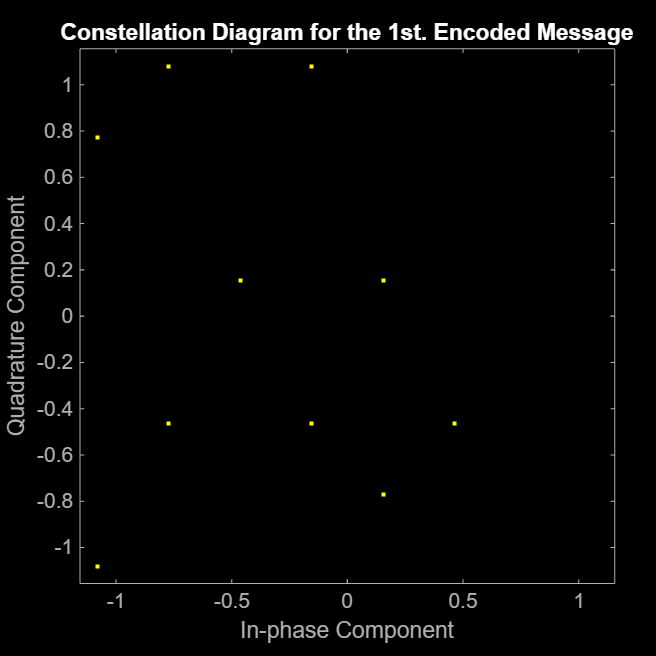

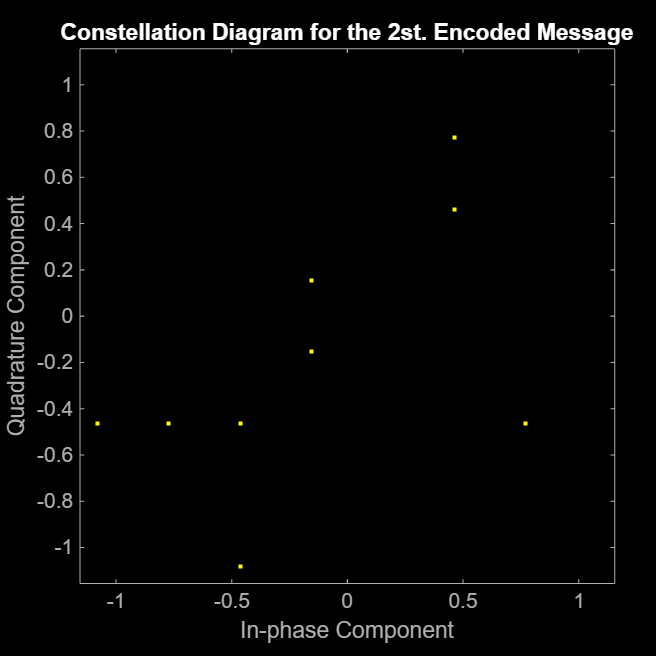

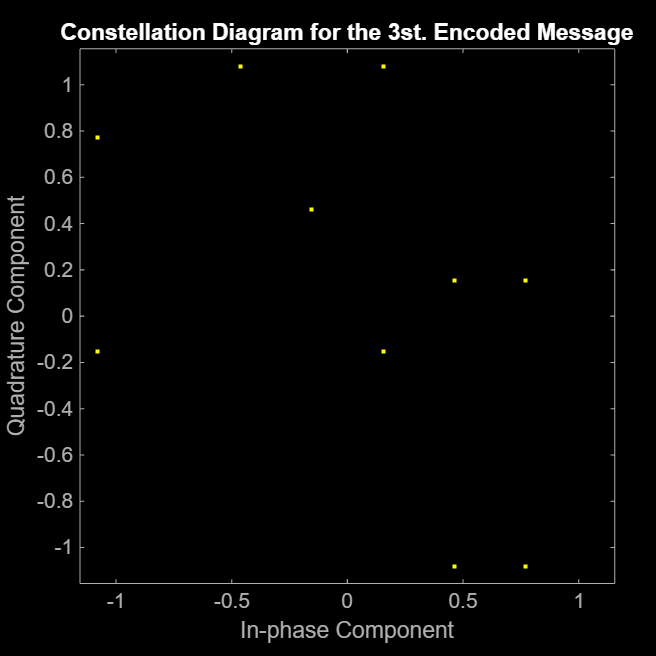

% Δείχνουμε τον αστερισμό για τα πρώτα 3 μηνύματα.
do_QAM64_5(3);

% Γενικά έχουμε έναν πίνακα ο οποίος έχει 100000 μηνύματα και κάθε μύνημα
% είναι σε ομάδες τον 6 bit τα οποία τώρα αναπαριστούνται σαν μυγαδικοί.
% round(56/6) = 10 (προς τα πάνω), άρα 10 columns.

## Ερώτημα 6ο

superpositionCoding_6_new();

## Ερώτημα 7ο

% Τώρα δημιουργούμε ένα Gaussian κανάλι με βάση την εκφώνηση και
% υπολογίζουμε ανάλογα με το SNR που μπαίνει σαν παράμετρο στην συνάρτηση
% την διασπορά. Τα μηνύματα που "περνάω" από το κανάλι είναι αυτά της
% ερώτησης 5, δηλαδή τα διαμοεφωμένα μηνύματα. Γενικά στο τέλος τα
% τελικά μηνύματα τα αποθηκευω σε ένα αρχειό mat, ώστε να τα επεξεργαστώ
% στην συνέχεια.
awgn_channel_7(15);
% Η είσοδος είναι μιγαδικοί και η έξοδος είναι πάλι μιγαδικός

### Για 8 δείτε πιο πάνω

% ...

## Ερώτημα 9

% Τώρα είμαστε στην πλευρά του δέκτη και κάνουμε αποδιαμόρφωση 64-QAM.
do_unQAM64_9(56); % Το μέγεθος των μηνυμάτων αμά δούμε από το ερώτημα 4 είναι 56.
% Σχηματίζω τα κανονικά μηνύματα από τους μιγαδικούς.

## Ερώτημα 10

% Δεν το έκανα

## Ερώτημα 11

apply_hamming_de_coding_11_b();
% Λοιπόν εδω κάνω de-hamming αλλά και διορθώνω τα λάθη. Γενικά έχω
% ακολουθήσει πάλι ακριβώς ότι λέει η διαφάνεια στο eclass. 
% Επίσης το έχω ελέγξει και χειροκίνητα και φαίνεται να δουλέυει σωστά.
% --

#### Ερώτημα 11 (remove πλεονασμό)

% Το επόμενο βήμα είναι να πεταχτουν τα bit πλεονασμού, τα οποία είναι τα
% parity bits (Ε0, Ε1 και Ε2)
% Θυμίζω η δομή των τελευταίων είναι 7-bit --> Π3 Π2 Π1 Ε2 Π0 Ε1 Ε0
% Άρα αυτά που θέλω εγώ να βγάλω είναι στην θέση 4, 6 και 7
% Αρα στη ακόλουθη συνάρτηση ξανα-ομαδοποιώ για κάθε μήνυμα επαναληπτικά τα
% 7-bit για κάθε segment του και βγάζω τα parity. 56/7 = 8.
remove_redundancy_11_c();

#### Ερώτημα 11 (πάλι CRC και συνολικά λάθοι)

% Τώρα θα παμε να ξανακανουμε CRC με βαση το ίδιο πολυώνυμο, 
% καθώς δέκτης και αποστολέας έχουνε συμφωνήσει στο ίδιο. 
% Θα πρέπει να δούμε τα τελευταία bits αν είναι σωστά (όλα 0) ή όχι.
% Γενικά είχα λίγο μπερδευτεί πως ακριβώς βλέπουμε αν υπάρχει λάθος αλλά
% με βοηθήσε το παρακάτω βίντεο.
% https://www.youtube.com/watch?v=6gbkoFciryA
[total_errors, num_messages] = applyCRC_11_d();
X = ['Total num of error: ', num2str(total_errors),'/', num2str(num_messages)];
disp(X); % Θυμίζω ότι αυτό είναι με SNR 15 (δες 7ο)

Total num of error: 98652/100000


#### Ερώτημα 12 και 8

% Τώρα θα δοκιμάσω για διάφορα SNR το PER που λαμβάνω στο κανάλι του Alice
% με Bob (μειούμενο 35dB (καλό καναλι) - 15dB (κακό καναλι))
% Ουσιαστικά θα πρέπει να τρέξουμε τις συναρτήσεις από ερώτημα 6 και μετά

SNR_range = 35:-1:15;
for SNR_dB = SNR_range
    % Bob
    awgn_channel_7(SNR_dB);
    do_unQAM64_9(56);
    apply_hamming_de_coding_11_b();
    remove_redundancy_11_c();
    
    [total_errors, num_messages] = applyCRC_11_d();
    error_rate_percentage = (total_errors / num_messages) * 100;
    X = ['BOB-SNR:', SNR_dB, ' - Total num of errors: ', num2str(total_errors), '/', num2str(num_messages), ' - ', num2str(error_rate_percentage), '%'];
    disp(X);

    % Eve, σύμφωνα με το ερώτημα 8 θα πρέπει το κανάλι της να είναι
    % χειρότερο, αρά -4 SNR. 
    SNR_dB_eve = SNR_dB - 4;
    awgn_channel_7(SNR_dB_eve);
    do_unQAM64_9(56);
    apply_hamming_de_coding_11_b();
    remove_redundancy_11_c();
    
    [total_errors, num_messages] = applyCRC_11_d();
    error_rate_percentage = (total_errors / num_messages) * 100;
    X = ['EVE-SNR:', num2str(SNR_dB_eve), ' - Total num of errors: ', num2str(total_errors), '/', num2str(num_messages), ' - ', num2str(error_rate_percentage), '%'];
    disp(X);
end

## TEST

SNR_dB_eve = 1;
    % EVE-SNR:15 - Total num of errors: 98669/100000 - 98.669%
    %awgn_channel_7(SNR_dB_eve);
    test();
    do_unQAM64_9(56);
    apply_hamming_de_coding_11_b();
    remove_redundancy_11_c();
    
    [total_errors, num_messages] = applyCRC_11_d();
    error_rate_percentage = (total_errors / num_messages) * 100;
    X = ['EVE-SNR:', num2str(SNR_dB_eve), ' - Total num of errors: ', num2str(total_errors), '/', num2str(num_messages), ' - ', num2str(error_rate_percentage), '%'];
    disp(X);

EVE-SNR:1 - Total num of errors: 98669/100000 - 98.669%
